# Equilibrium Time Heat Distribution in Circular Disk

clear, clc;

dr = 0.01;
r = 1;
do = 0.05;
o = 2*pi;

lr = length(dr:dr:r);
lo = length(do:do:o);
u = zeros(lr,lo);

[x,y] = meshgrid(dr:dr:r,do:do:o);
x = x'; y = y';

bc = ones(1,lo);

colormap("jet")

## Use Fourier Series

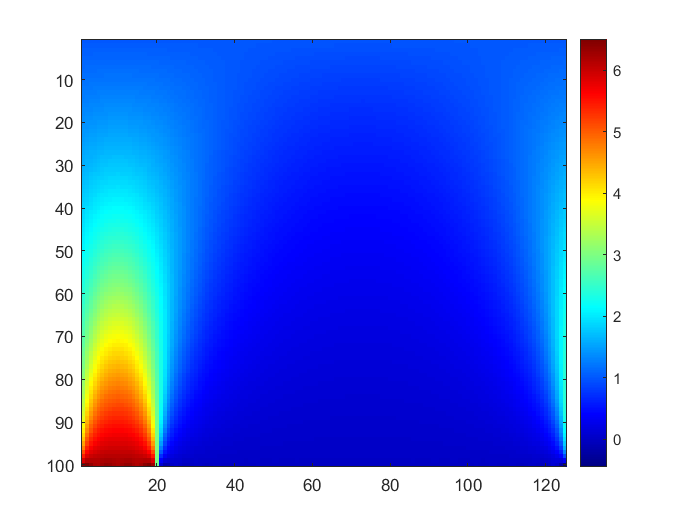

A0 = (1/(2*pi)) * sum(bc.*ones(1,lo)) * do;
u = u + A0;
for i=1:100
    An = (1/pi) * sum(bc.*cos(i*(do:do:o)/o)) * do;
    Bn = (1/pi) * sum(bc.*sin(i*(do:do:o)/o)) * do;
    u = u + An*(x.^i).*cos(i*y) + Bn*(x.^i).*sin(i*y);
end

imagesc(u);
colorbar;